# EL6023 Final Project

Amritpal Singh

Kubilay Ulger

In this project we simulate transmission through a MIMO channel using data from Minsheng's data set. 

## Loading Data and Getting Path Information

Loading Data

clear all %Fresh start
clc 
load roomPathData.mat

Selecting a Rx's with LOS, Getting the path delays, gains and angle of arrivals/departures f

LinkStates = pathData.linkState;
LOS = find(LinkStates==1); %indices for LOS links
NLOS = find(LinkStates==2); %Used later

rxNum = LOS(randi([1,length(LOS)])); %Selecting an RX number from LOS indices

txPos = pathData.txPos; %Getting tx Position

rxPos = pathData.rxPos(rxNum,:); %Getting rx Position

npaths = pathData.npaths(rxNum,:); %Number of paths
gain = pathData.gain(rxNum,:); %Gain of each path
dly = pathData.dly(rxNum,:); %Delay of each path

% Angles 
aoaAz = pathData.aoaAz(rxNum,:)';
aoaEl = pathData.aoaEl(rxNum,:)';
aodAz = pathData.aodAz(rxNum,:)';
aodEl = pathData.aodEl(rxNum,:)';

%We may wish to Rx and Tx towards each other so calculating some parameters
trVec = rxPos' - txPos; %Vector from tx to rx
trVec = trVec/norm(trVec);
zvec = [0,0,1]'; %Antenna elements are directed towards +z by default

tiltAx = cross(zvec,[trVec;0]);
tiltAngle = 90; %Since tiltAx,trVec and zVec are mutually orthogonal


Creating 2 antenna elements, boresights directed to each other

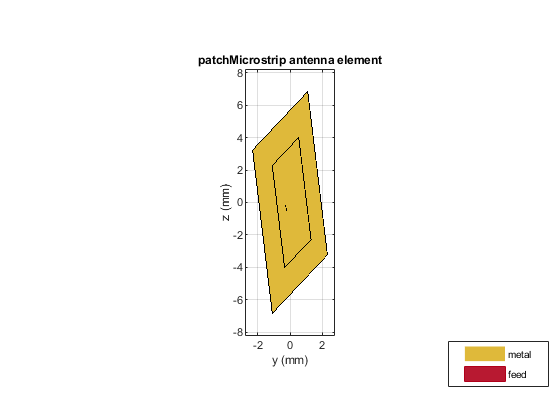

fc = pathData.fc; %Carrier Frequency
elemTx = design(patchMicrostrip, fc); %Simple antenna element
elemTx.Tilt = 90; 
elemTx.TiltAxis = tiltAx';

elemRx = design(patchMicrostrip, fc); %Simple antenna element
elemRx.Tilt = 90; 
elemRx.TiltAxis = -tiltAx';

%Displaying Antennas
elemTx.show()
view(90,0);

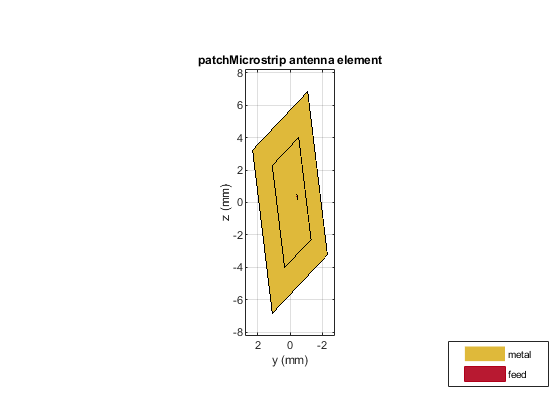

elemRx.show()
view(-90,0);

You can see that antennas are directed at each other.

**Antenna platforms**

%We took these antenna numbers from a demo, they are the usual arrays in
%mmWave
nantgNB = [4,4]; % 16 Antennas at transmitter
nantUE = 8; % 8 Antennas at receiver

lambda = physconst('LightSpeed')/fc; %Wavelength
dstep = lambda/2; %Distance between antennas

arrgNB = phased.URA(nantgNB,dstep,"ArrayNormal","x"); %URA for transmitter
arrUE = phased.ULA(nantUE,dstep,"ArrayAxis","y"); %ULA for receiver

arrPlatformgNB = ArrayPlatform('elem', elemTx, 'arr', arrgNB, 'fc', fc);
arrPlatformgNB.computeNormMatrix();

arrPlatformUE =  ArrayPlatform('elem', elemRx, 'arr', arrUE, 'fc', fc);
arrPlatformUE.computeNormMatrix();

Looking at Tx and Rx antennas directivity patterns

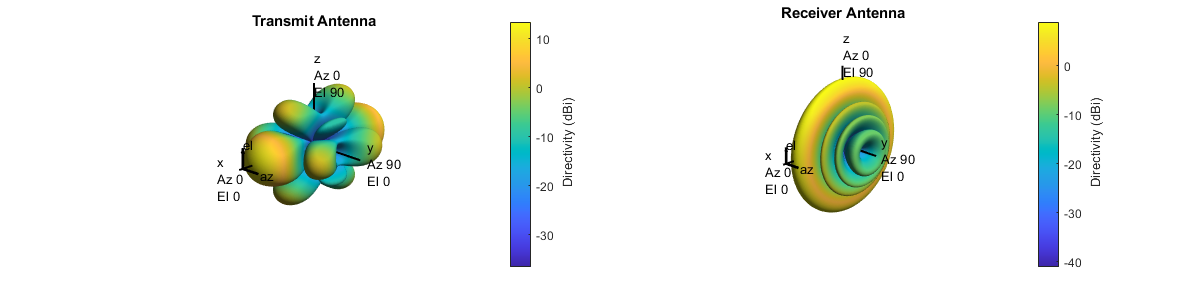

figure(1)
set(gcf,'position',[0,0,1200,300]);
subplot(1,2,1)
arrgNB.pattern(fc);
title('Transmit Antenna')
subplot(1,2,2);
arrUE.pattern(fc);
title('Receiver Antenna')

## **OFDM CHANNEL**

We used the FDMIMOChan class from Lab8 to get chanGrid and the transmitter side average Q=H'*H that will be used in calculating Precoder

SubcarrierSpacing = 120;    % SCS in kHZ
NRB = 61;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB

carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformgNB, 'rxArrPlatform', arrPlatformUE, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl,  ...
    'gain', gain, 'dly', dly, 'fc', fc);

frameNum = 0;
slotNum = 0;
[chanGrid, Q] = fdchan.step(frameNum, slotNum); %chanGrid is equalized to make numbers look better, we only care about SNR and relative gains

## Transmitter

Now for the transmitter we create a pdfschConfig as usual. So we create a tx object. We kept NumLayers = 1 and generated nstreams of OFDM grids in step function manually

mcsInd = 10;

Modulation = '16QAM';
targetCodeRate = 340/1024;

pdschConfig = nrPDSCHConfig(...
    'Modulation', Modulation, ...
    'PRBSet', (0:NRB-1), ...
    'SymbolAllocation', [1, waveformConfig.SymbolsPerSlot-1], ...
    'PTRS', nrPDSCHPTRSConfig(),...
    'NumLayers', 1);
tx = NRgNBTxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);

So we first we need to pick nstreams such that 1 <= nstreams <= min(Ntx,Nrx) where Ntx and Nrx are transmitter and receiver antenna # respectively

nStreams = 5; %Chosen for dmeonstration

[txGrid,Fprecoder] = tx.step(nStreams,Q);
%The output txGrid is the precoded inside, Tx divides unit power equally
%across nstreams so E||x||^2=1 where x is a vector of size nstreams x 1

## **Channel Operation**

Now we pass precoded grid through the chanGrid and add noise

G = pagemtimes(chanGrid,Fprecoder); %Pre-coded channel, it's assumed that RX knows this.
AvgSNR = 10; %Let's assume this is the SNR we have, we will pick noise variance to match this.
noiseVar = sum(mean(abs(G).^2,[3,4]),'all')/db2pow(AvgSNR)/nantUE/nStreams;

%Now we pass txGrid through the channel and add noise to obtain received
%grid txGrid
rxGridNoNoise = pagemtimes(chanGrid,txGrid);
rxGrid = rxGridNoNoise + sqrt(noiseVar/2)*(randn(size(rxGridNoNoise))+1j*randn(size(rxGridNoNoise)));

## Receiver

Now we have to perform LMMSE and Decoding to get the received bits! This is all done in UE class. We have modified the UE class from lab 4 to handle LMMSE and multi layer decoding. So we just create an RX object and pass rxGrid, G, noiseVar and nStreams.

rx = NRUERxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);
rx.step(rxGrid, G, noiseVar,nStreams); %Demodulation

## Testing

%Now we test if we got a throughput
rxBits = rx.rxBits;
txBits = tx.txBits;

CorrectBits = length(find(rxBits == txBits));
TotalBits = length(txBits);


fprintf('%d,%d',CorrectBits,TotalBits)

46443,57640

Now that we know our model works we can try out different nStreams and different MCS. The MCS table can be found below.

## Analysis

We created a seperate .m file that runs a simulation through different MCS values and then saves the results to simulation.mat. We will now load the data and obtain graphs.

load simulation.mat
rxNum = Sim.rxNum; %The picked rx
MCS = Sim.MCS; %Tested MCS indices
nStreams = Sim.NumLayers; %Tested nStreams
ErrorRates = Sim.Error; %Error rates for all tests

First lets see where does our Rx sits in the DataMap

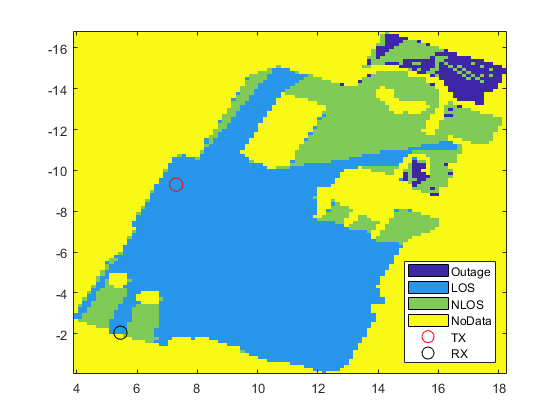

rxPosAll = pathData.rxPos;
mapper = DataMapper(rxPosAll, pathData.posStep);
figure(3)
noDataValue = 3;  % Use this value for positions with no data

% Legend labels
legendLabels = {'Outage', 'LOS', 'NLOS', 'NoData'};

% Call the plot.  Use `plotHold=true` to hold the plot so we can overlay
% other items
mapper.plot(pathData.linkState, 'noDataValue', noDataValue, ...
    'LegendLabels', legendLabels, 'plotHold',true);

% Overlay the TX position
txPos = pathData.txPos;
plot(txPos(1), txPos(2), 'ro', 'MarkerSize', 10, 'DisplayName', 'TX');
plot(rxPosAll(rxNum,1), rxPosAll(rxNum,2), 'ko', 'MarkerSize', 10, 'DisplayName', 'RX');
hold off;

% Display the legend
legend('Location', 'SouthEast');

Now that we have a visual we can compare what happens when we pick different nstreams and MCS.

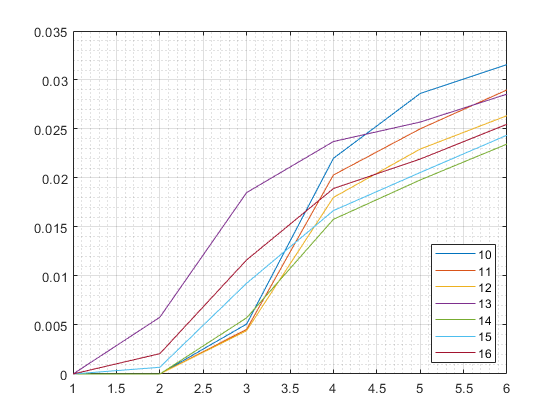

figure(4)
plot(nStreams,ErrorRates(1,:),'LineWidth',1.4)
hold on
plot(nStreams,ErrorRates(2,:),'LineWidth',1.4)
plot(nStreams,ErrorRates(3,:),'LineWidth',1.4)
plot(nStreams,ErrorRates(4,:),'LineWidth',1.4)
plot(nStreams,ErrorRates(5,:),'LineWidth',1.4)
plot(nStreams,ErrorRates(6,:),'LineWidth',1.4)
plot(nStreams,ErrorRates(7,:),'LineWidth',1.4)
xlabel('Number of Streams')
ylabel('Error Rate')
hold off
grid on
grid minor
labels = {'10','11','12','13','14','15','16'};
legend(labels,'Location','southeast')

As can be seen as number of streams increase error rates goes up. This gives us a trade of between rate and error. As we get higher streams out rate will increase since each channel use we send more symbols.

Figure is added for reference.